# Script to generate and compare breast cancer specific models

*Created by Michiel Adriaens (MaCSBio, Maastricht University, 19-06-2024)*

*Remark**: first run the FBA_normal script from the practical up to Section 2 to create the required healthy cell model.*

## Section 1: Create a reference cancer model and a cancer model with additional gene deletions

% Import the gene expression data
gxData = readtable('BreastCancer_geneExpressionData.txt'); 

% Create an index of all genes with expression of 0
index = string(table2array(gxData(:,3))) == '0';

% Remove genes with 0 expression from model
genesToRemove = intersect(table2cell(gxData(index,2)), modelRPMI.genes);
[modelRPMIcancer, hasEffect, constrRxnNames, deletedGenes] =... 
    deleteModelGenes(modelRPMI, genesToRemove);

% Option: remove one or more additional genes from the model (e.g. inhibition by drugs, knock-out or loss-of-function)
% HGNC ID	HGNC symbol
% -------       -----------
% HGNC:10924    MCT3
% HGNC:6544	LDHC
genesToRemoveAdd = genesToRemove;
genesToRemoveAdd{end + 1} = 'HGNC:14025';
genesToRemoveAdd{end + 1} = 'HGNC:10966';
genesToRemoveAdd{end + 1} = 'HGNC:10969';
genesToRemoveAdd{end + 1} = 'HGNC:1937';
genesToRemoveAdd{end + 1} = 'HGNC:1938';
[modelCadd, hasEffect, constrRxnNames, deletedGenes] =... 
    deleteModelGenes(modelRPMI, genesToRemoveAdd);


## Section 2: Simulate ATP production in cancer cells under aerobic conditions

Let's perform the flux balance analysis for an aerobic cancer model and the cancer cell model with additional gene deletions:

% Reference model
modelaerobicC = modelRPMIcancer;
modelaerobicC = changeObjective(modelaerobicC, 'DM_atp_c_');
modelaerobicC = changeRxnBounds(modelaerobicC, 'EX_o2(e)', -1000, 'l');
FBAaerobicC = optimizeCbModel(modelaerobicC, 'max');

% Model with additional gene deletions
modelaerobicCadd = modelCadd;
modelaerobicCadd = changeObjective(modelaerobicCadd, 'DM_atp_c_');
modelaerobicCadd = changeRxnBounds(modelaerobicCadd, 'EX_o2(e)', -1000, 'l');
FBAaerobicCadd = optimizeCbModel(modelaerobicCadd, 'max');


## Section 3: Compare results  

Let's visualize the results by focussing on reactions involving lactate in the cytosol.

Start_time = '2025_6_28_18_12_42.794'

Biograph object with 38 nodes and 46 edges.


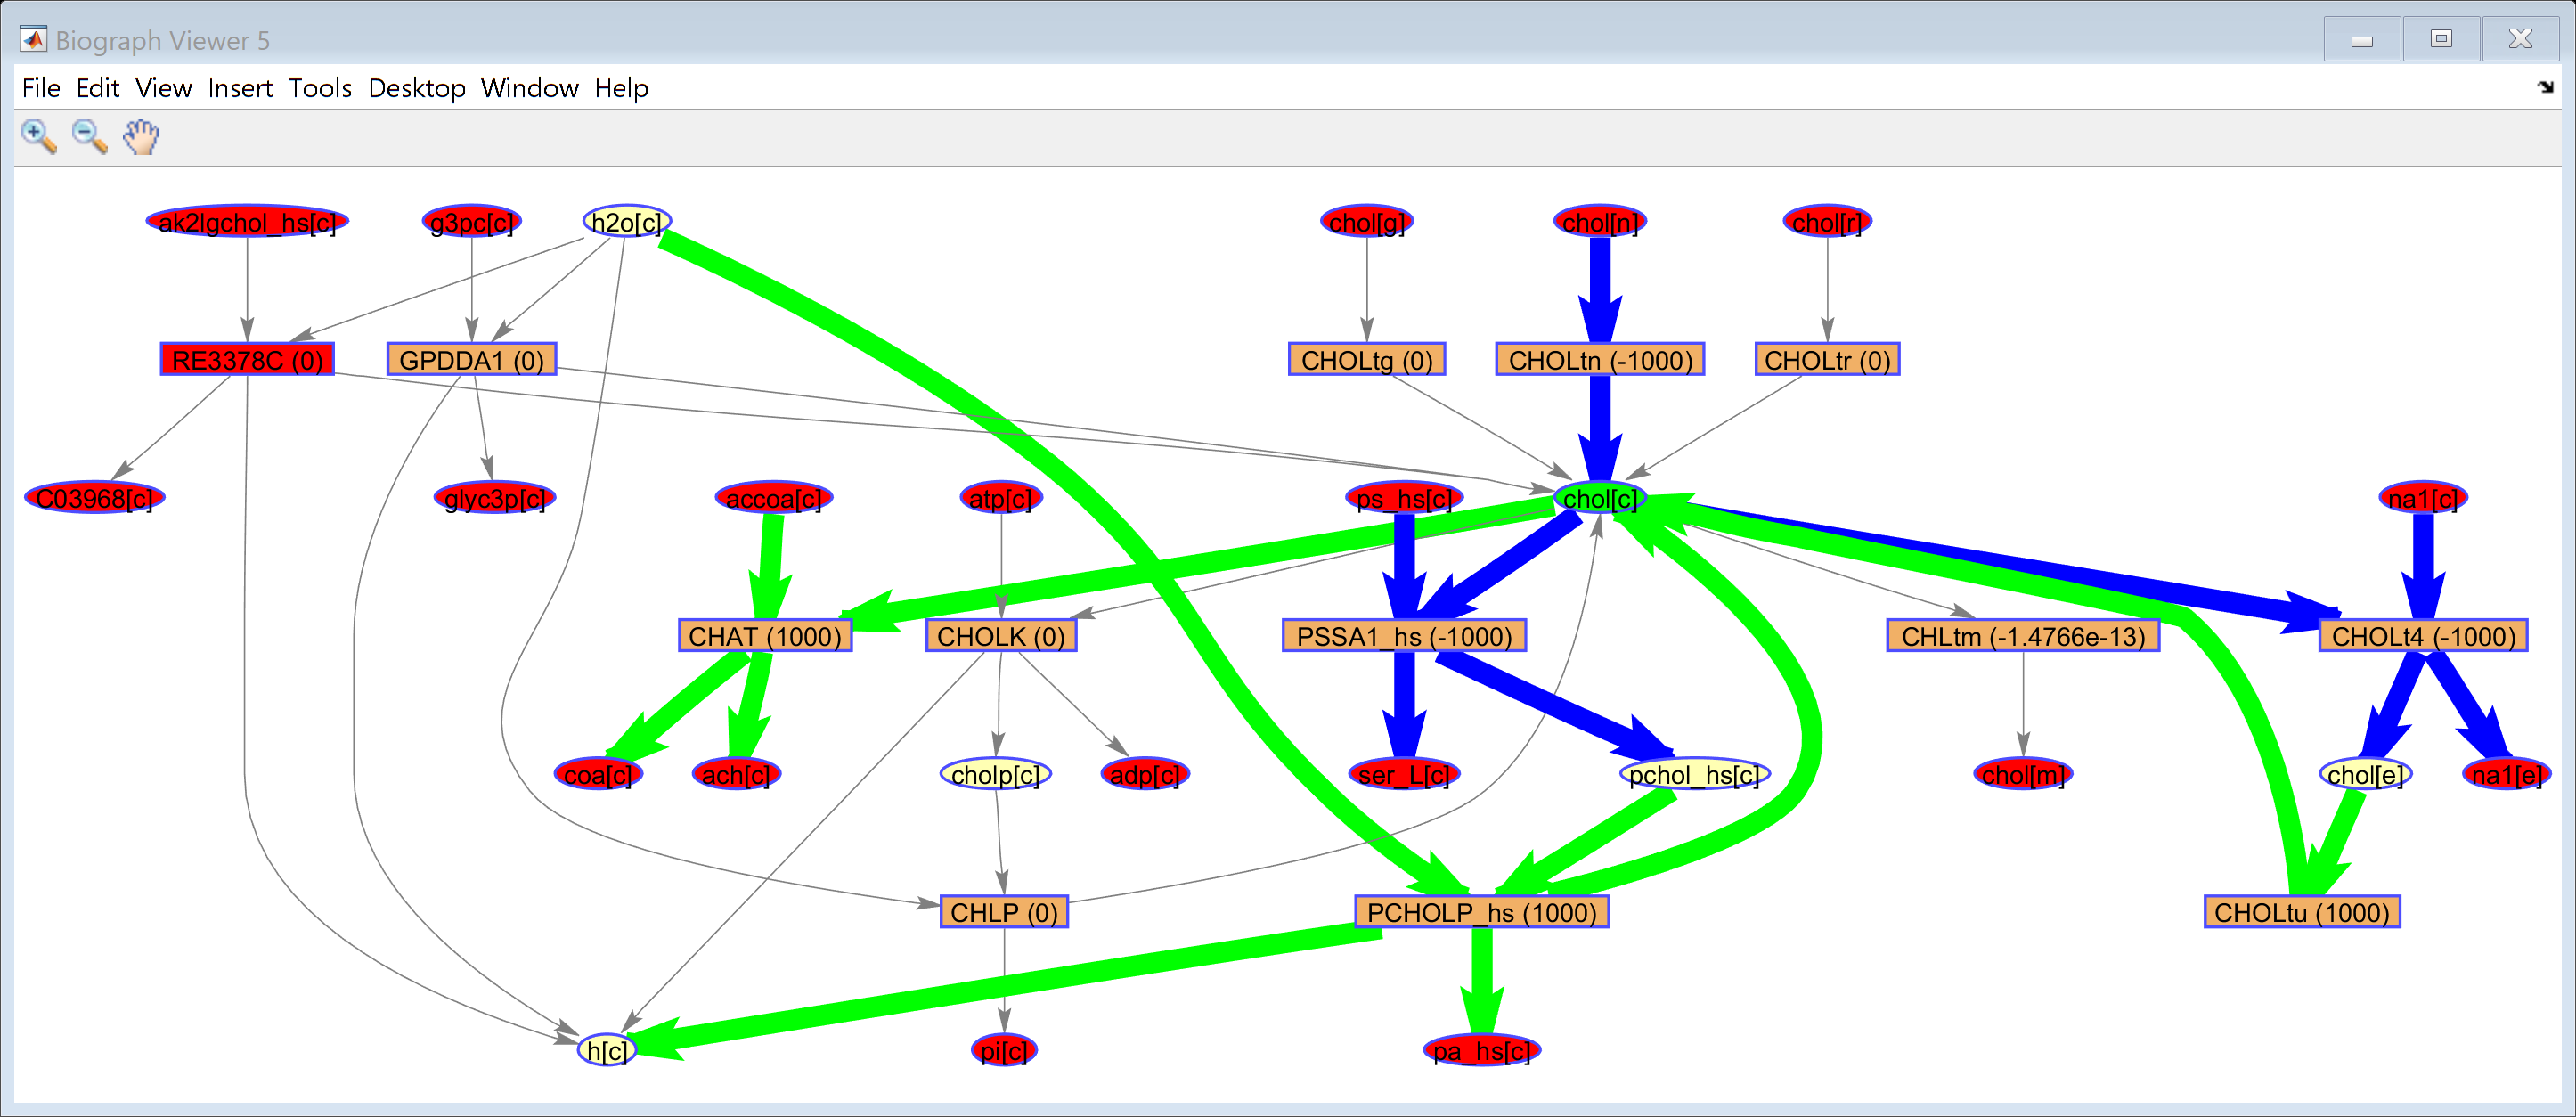

End_time = '2025_6_28_18_12_48.299'

Total_time = '0_0_0_0_0_5.505'

% Run all sections in this model 
% it is also no needed to run FBA cancer model as cancer is incluced
% Aerobic in cancer model
draw_by_met(model, {'chol[c]'},...
    'true', 1, 'struc', {''}, FBAaerobicC.v);

Start_time = '2025_6_28_18_12_48.311'

Biograph object with 38 nodes and 46 edges.


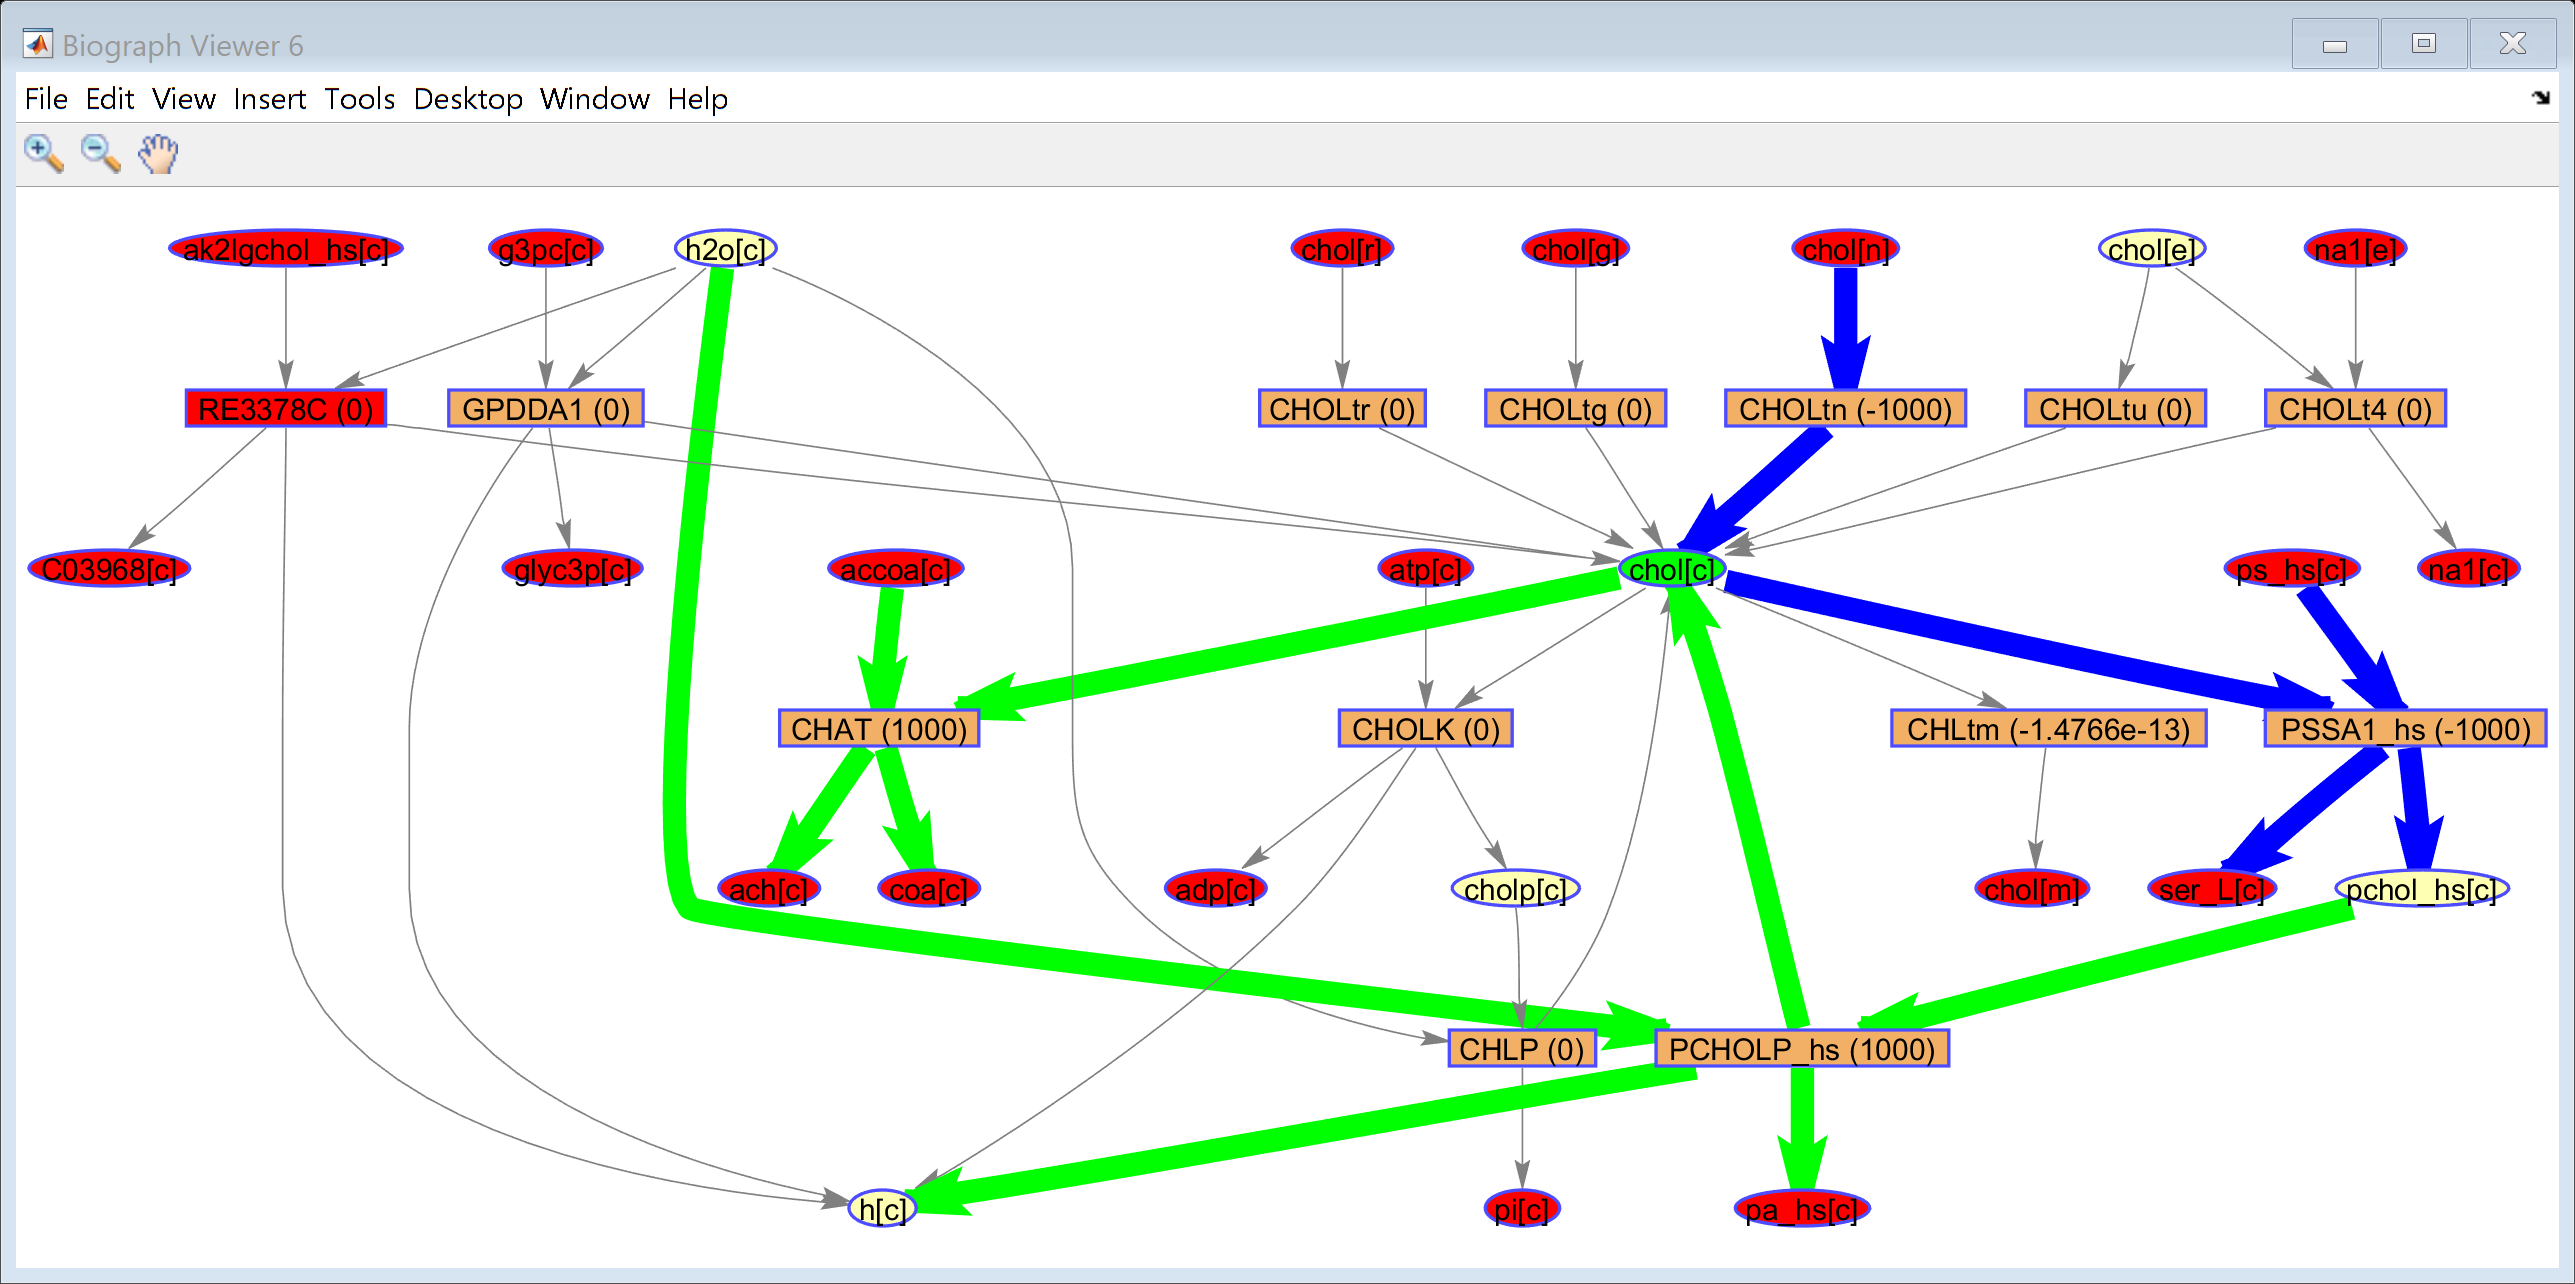

End_time = '2025_6_28_18_12_53.652'

Total_time = '0_0_0_0_0_5.341'


% Aerobic in cancer model with additional gene deletions
draw_by_met(model, {'chol[c]'},...
    'true', 1, 'struc', {''}, FBAaerobicCadd.v);

The code below enables you to identify reactions with large absolute differences. Combine it with the graphs above to identify reactions of interest and interpret the change (e.g. larger flux, smaller flux, switch from positive to negative flux, etc.).

Start_time = '2025_6_28_18_12_53.66'

Biograph object with 38 nodes and 46 edges.


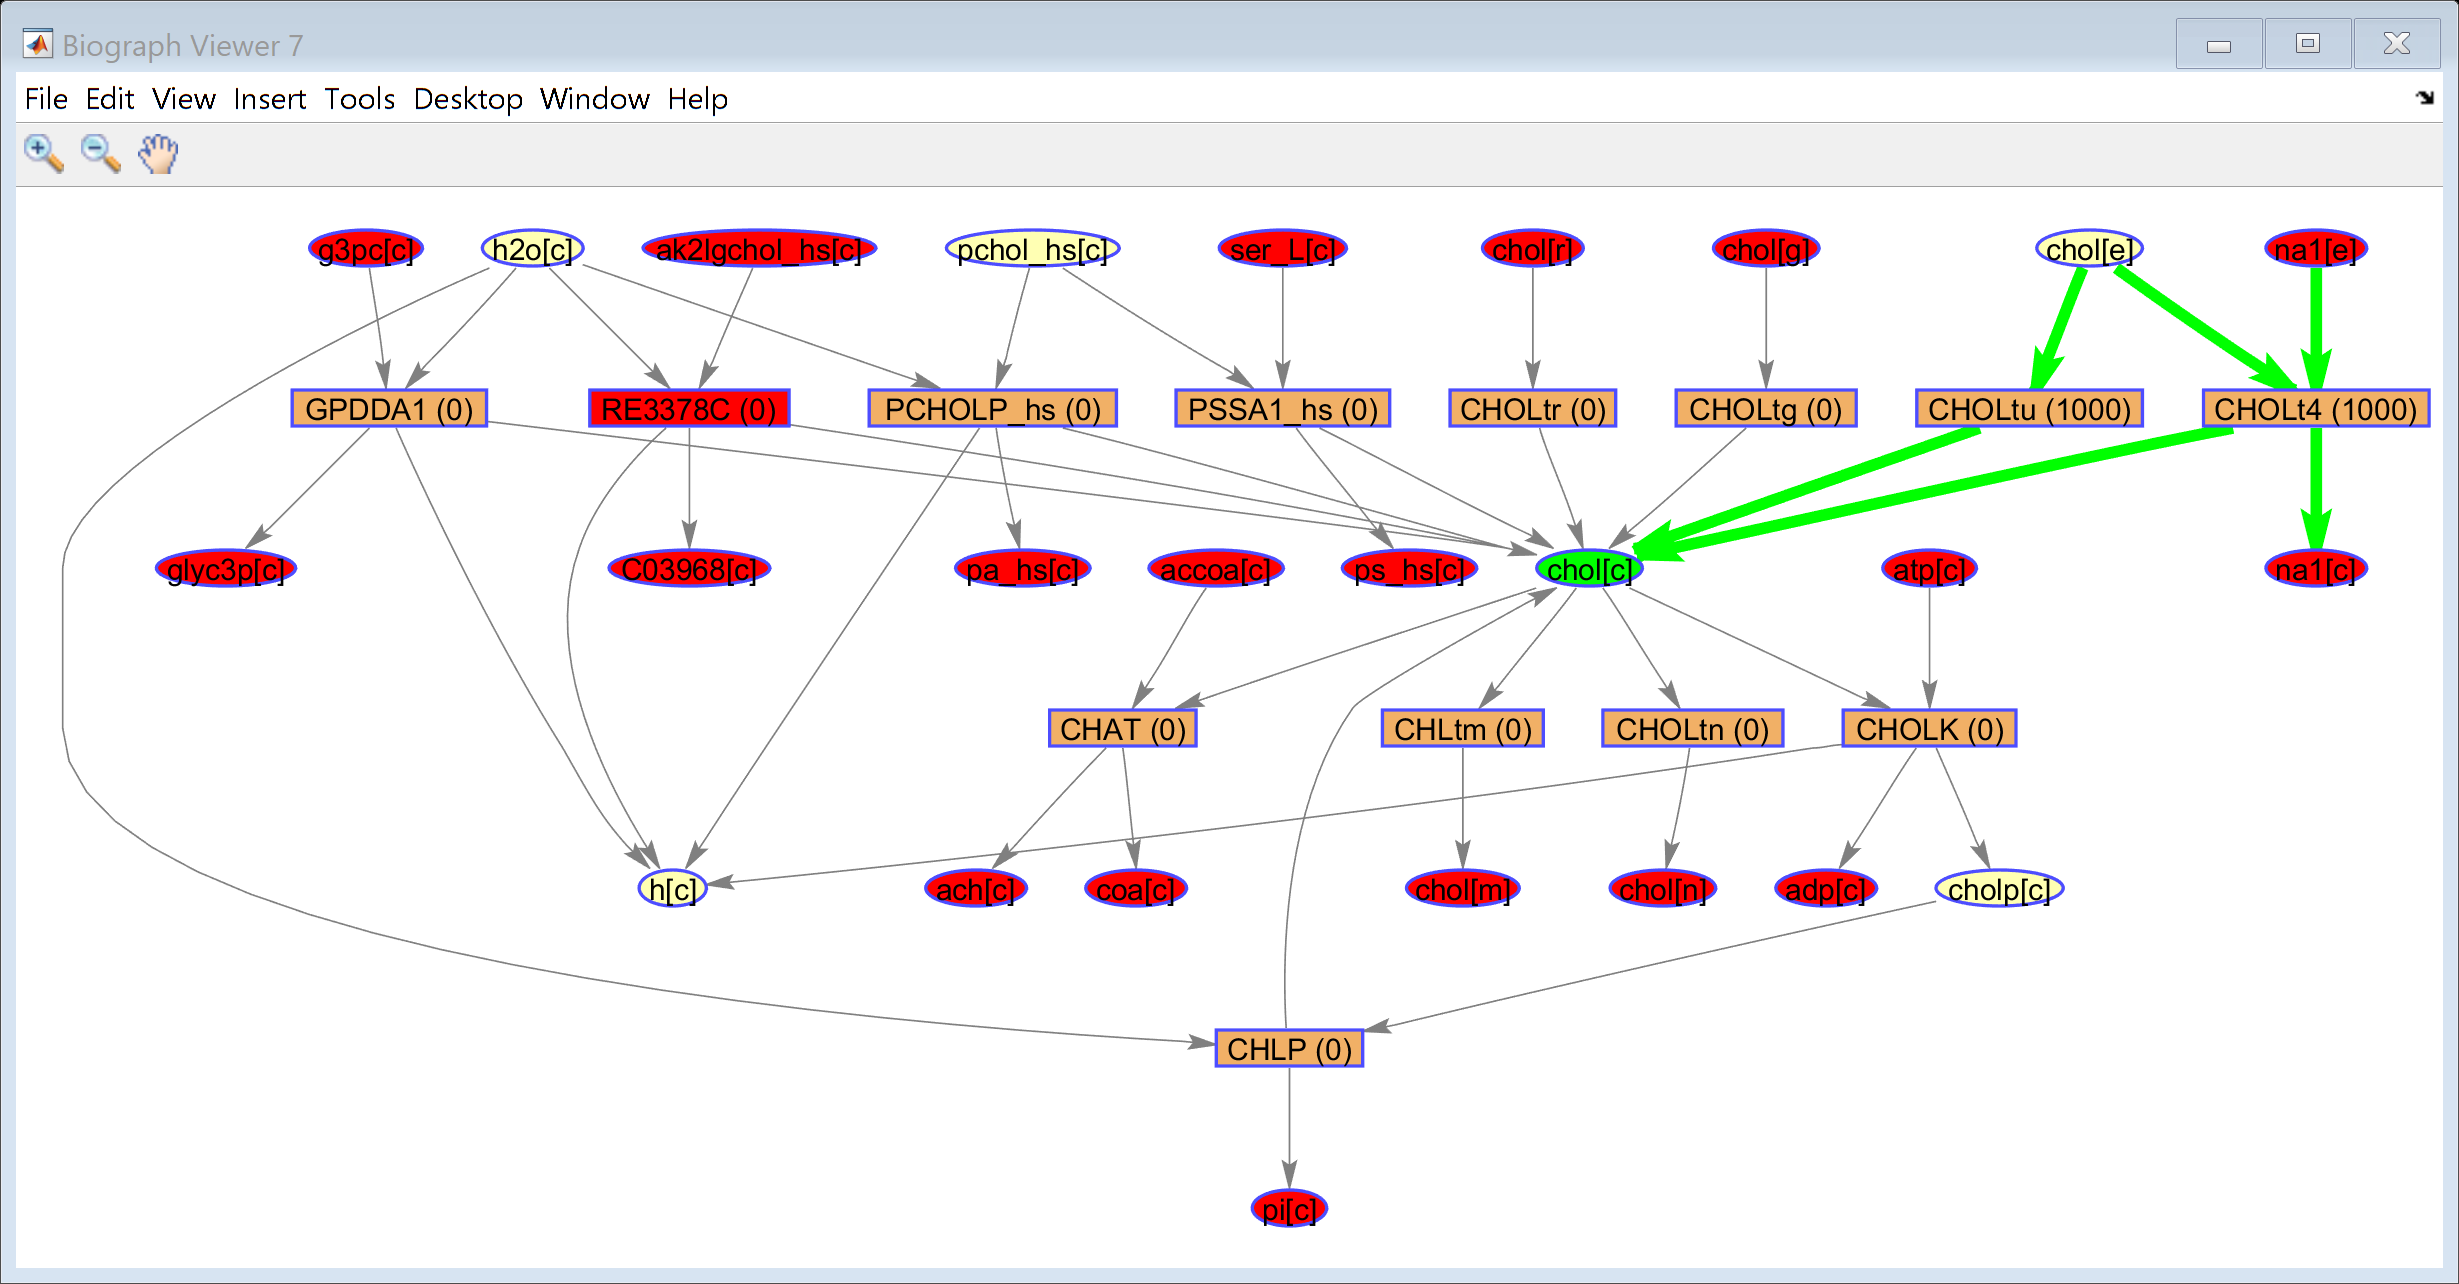

End_time = '2025_6_28_18_12_59.284'

Total_time = '0_0_0_0_0_5.624'


% Visualize the absolute difference between the cancer model and model with additional gene deletions. This will make
%  finding reactions of interest a bit easier (the thicker the arrow = the bigger the difference = the more interesting!)
FBAdiffC = FBAaerobicCadd;
FBAdiffC.v = abs(round(FBAaerobicCadd.v - FBAaerobicC.v));
draw_by_met(model, {'chol[c]'},...
    'true', 1, 'struc', {''}, FBAdiffC.v);

**~ END OF SCRIPT ~**

%Get index of a specific reactions and determine flux
rxnID = 'CHOLt4';
rxnIndex = find(strcmp(model.rxns, rxnID));
flux_cancer = FBAaerobicC.v(rxnIndex);   % e.g., from FBAaerobicC
flux_Cadd = FBAaerobicCadd.v(rxnIndex);   % e.g., from FBAaerobicCadd